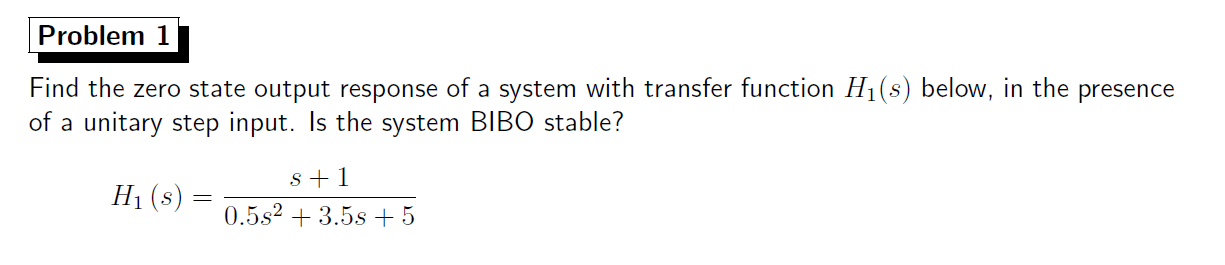

% syms t f H s
s=tf('s')

s =
 
  s
 
Continuous-time transfer function.



H=(s+1)/(.5*s^2+3.5*s+5)

H =
 
         s + 1
  -------------------
  0.5 s^2 + 3.5 s + 5
 
Continuous-time transfer function.




zpk(H)  %zero pole gain model to see immediately the poles(zeros of denominator) and the zeros

ans =
 
    2 (s+1)
  -----------
  (s+5) (s+2)
 
Continuous-time zero/pole/gain model.




eig(H)

ans =     -5
    -2


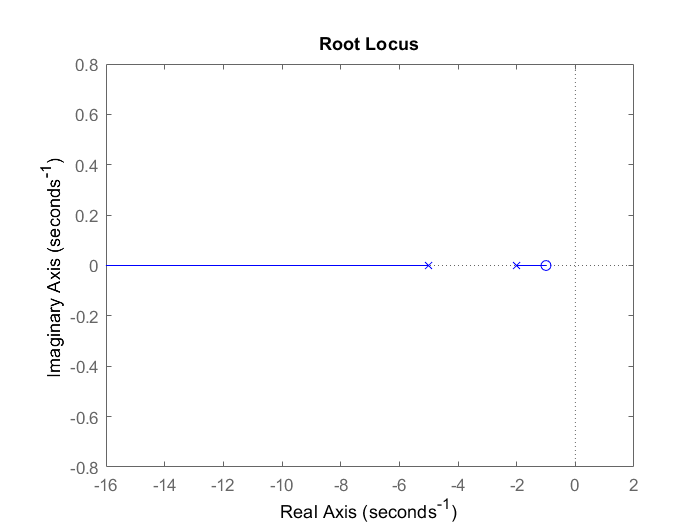

rlocus(H,'b')


% simulink;
% sim("ex1.slx");


The system is BIBO because the real part of the poles is negative.

## **RESIDUAL METHOD**

Y=zpk(minreal( H*1/s))

Y =
 
     2 (s+1)
  -------------
  s (s+5) (s+2)
 
Continuous-time zero/pole/gain model.



pole(Y)

ans =      0
    -5
    -2


eig(Y)

ans =      0
    -5
    -2



[N,D]=tfdata(Y,'v')

N =      0     0     2     2


D =      1     7    10     0


[r,p]=residue(N,D)

r =    -0.5333
    0.3333
    0.2000


p =     -5
    -2
     0


The system is BIBO because the real part of the poles is negative.

## **SYMBOLIC METHOD**

clear
syms t f H s

H=(s+1)/(.5*s^2+3.5*s+5)

$$H = \frac{s+1}{\frac{s^{2}}{2}+\frac{7\,s}{2}+5}$$

f=piecewise(t<0, 0,t>=0,1)

$$f = \left\{ \begin{array}{cl} 0 & \text{ if }t<0\\ 1 & \text{ if }0\leq t \end{array}\right.$$



y=vpa(simplify(ilaplace(laplace(f)*H)),4)

$$y = 0.3333\,{\mathrm{e}}^{-2.0\,t}-0.5333\,{\mathrm{e}}^{-5.0\,t}+0.2$$

The system is BIBO because the real part of the poles is negative.